clear;
clc;

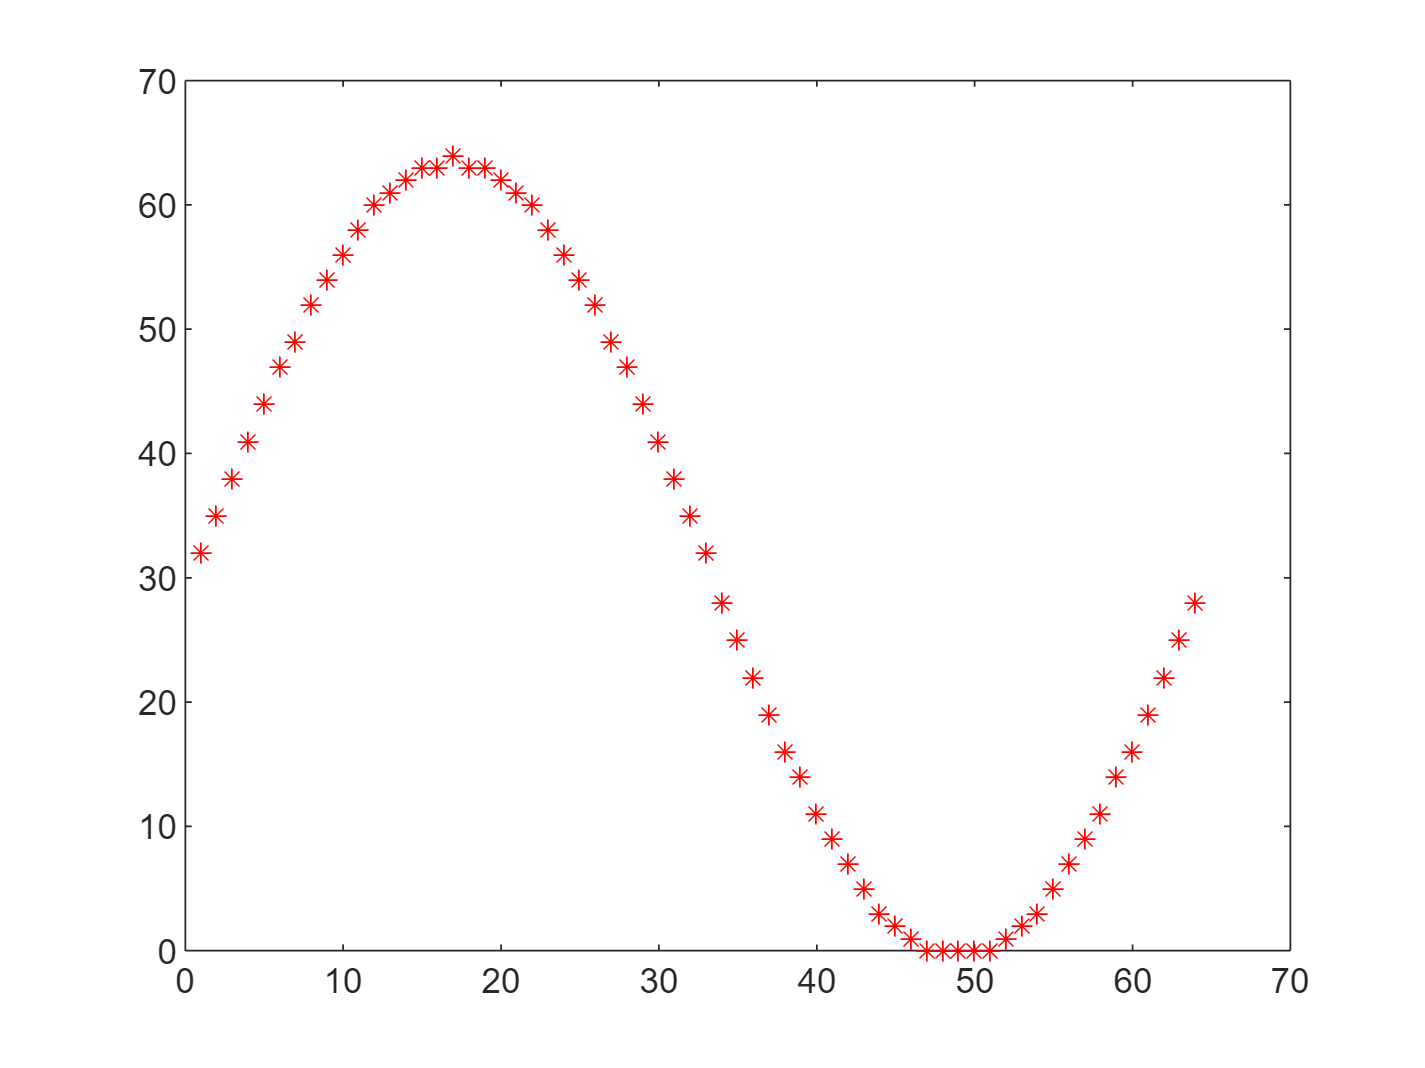

a = [32,35,38,41,44,47,49,52,54,56,58,60,61,62,63,63,64,63,63,62,61,60,58,56,54,52,49,47,44,41,38,35,32,28,25,22,19,16,14,11,9,7,5,3,2,1,0,0,0,0,0,1,2,3,5,7,9,11,14,16,19,22,25,28];
x1 = 1:1:64;
plot(x, a, '*r')

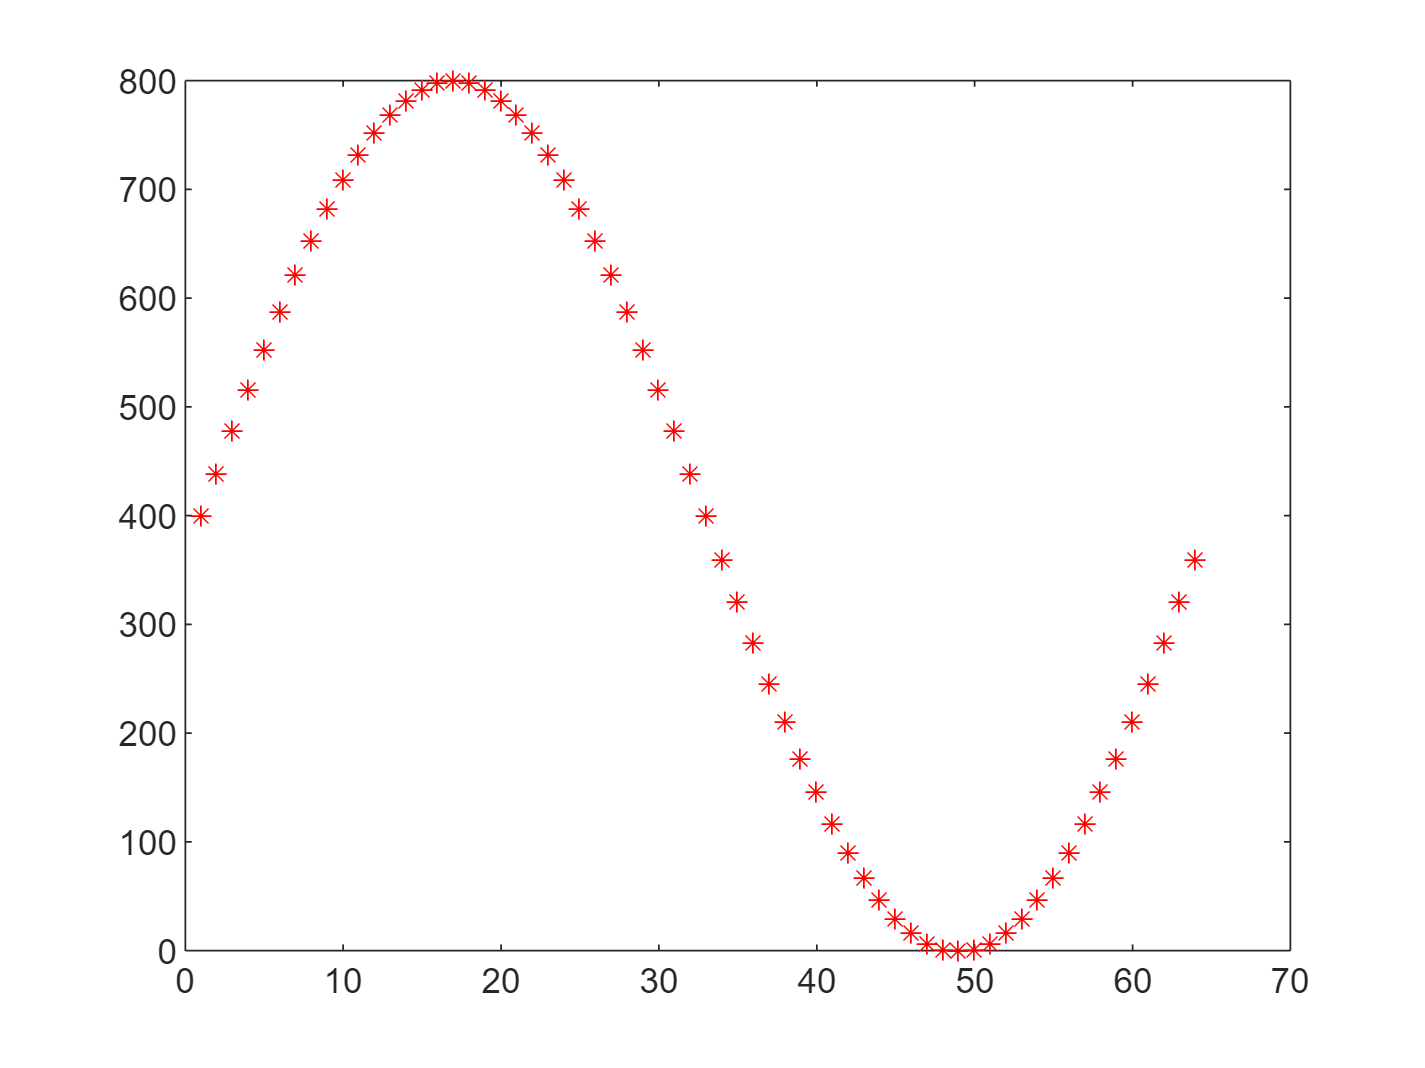

b = [400,439,478,516,553,588,622,653,682,709,732,752,769,782,792,798,800,798,792,782,769,752,732,709,682,653,622,588,553,516,478,439,400,360,321,283,246,211,177,146,117,90,67,47,30,17,7,1,0,1,7,17,30,47,67,90,117,146,177,211,246,283,321,360];
plot(x1, b, '*r')

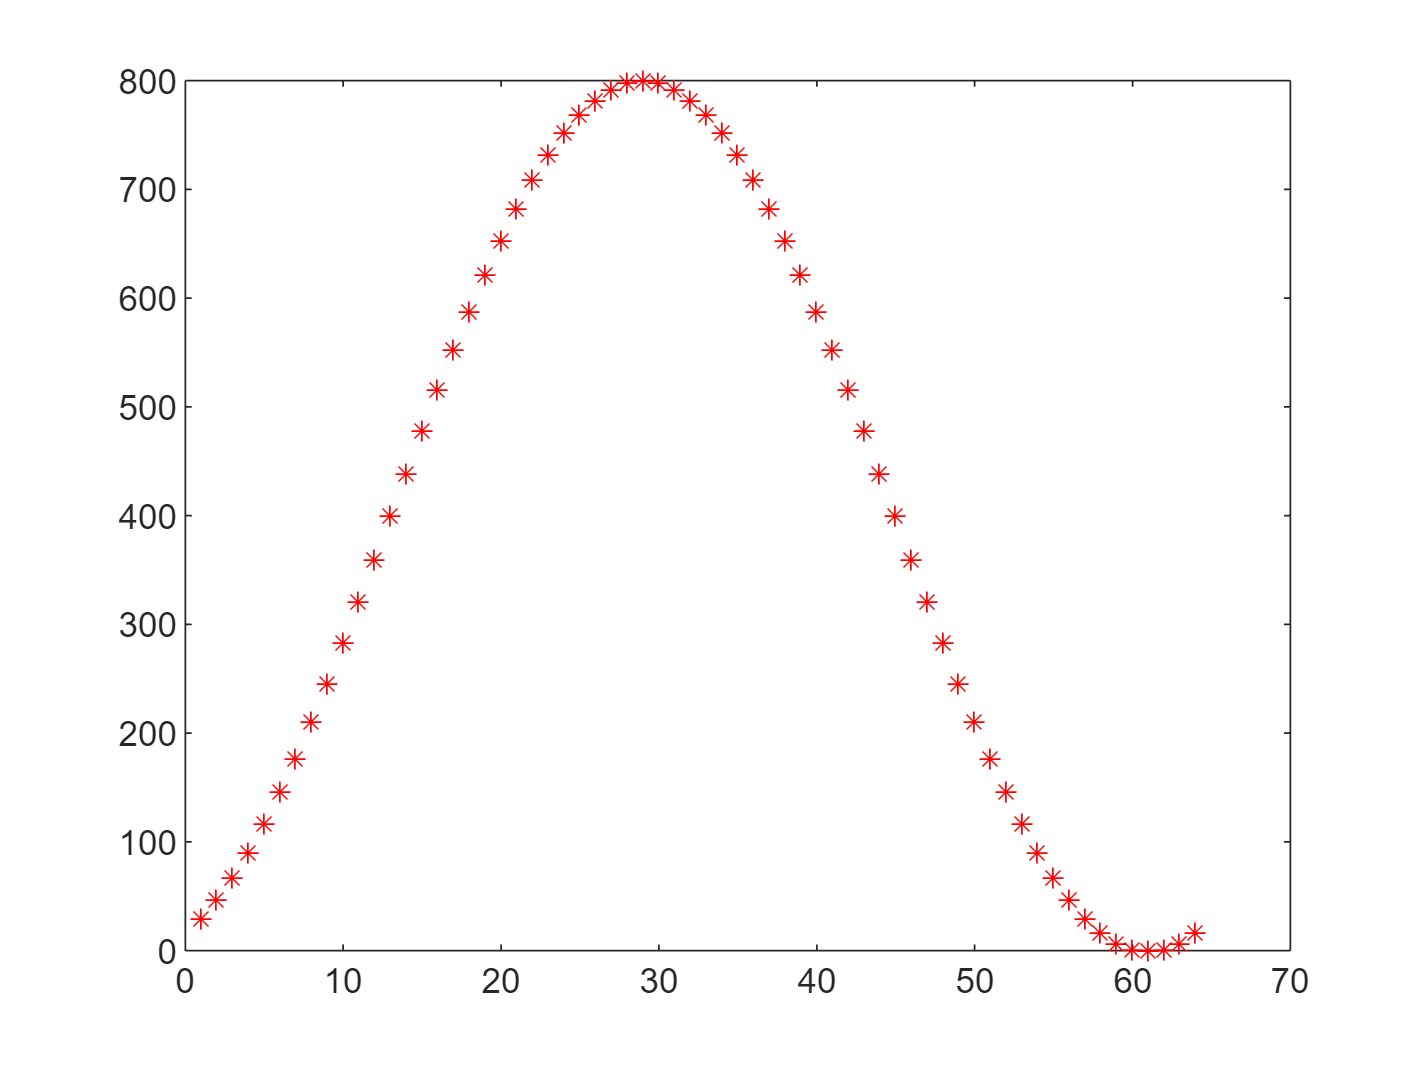

c = [30,47,67,90,117,146,177,211,246,283,321,360,400,439,478,516,553,588,622,653,682,709,732,752,769,782,792,798,800,798,792,782,769,752,732,709,682,653,622,588,553,516,478,439,400,360,321,283,246,211,177,146,117,90,67,47,30,17,7,1,0,1,7,17];
plot(x, c, '*r')

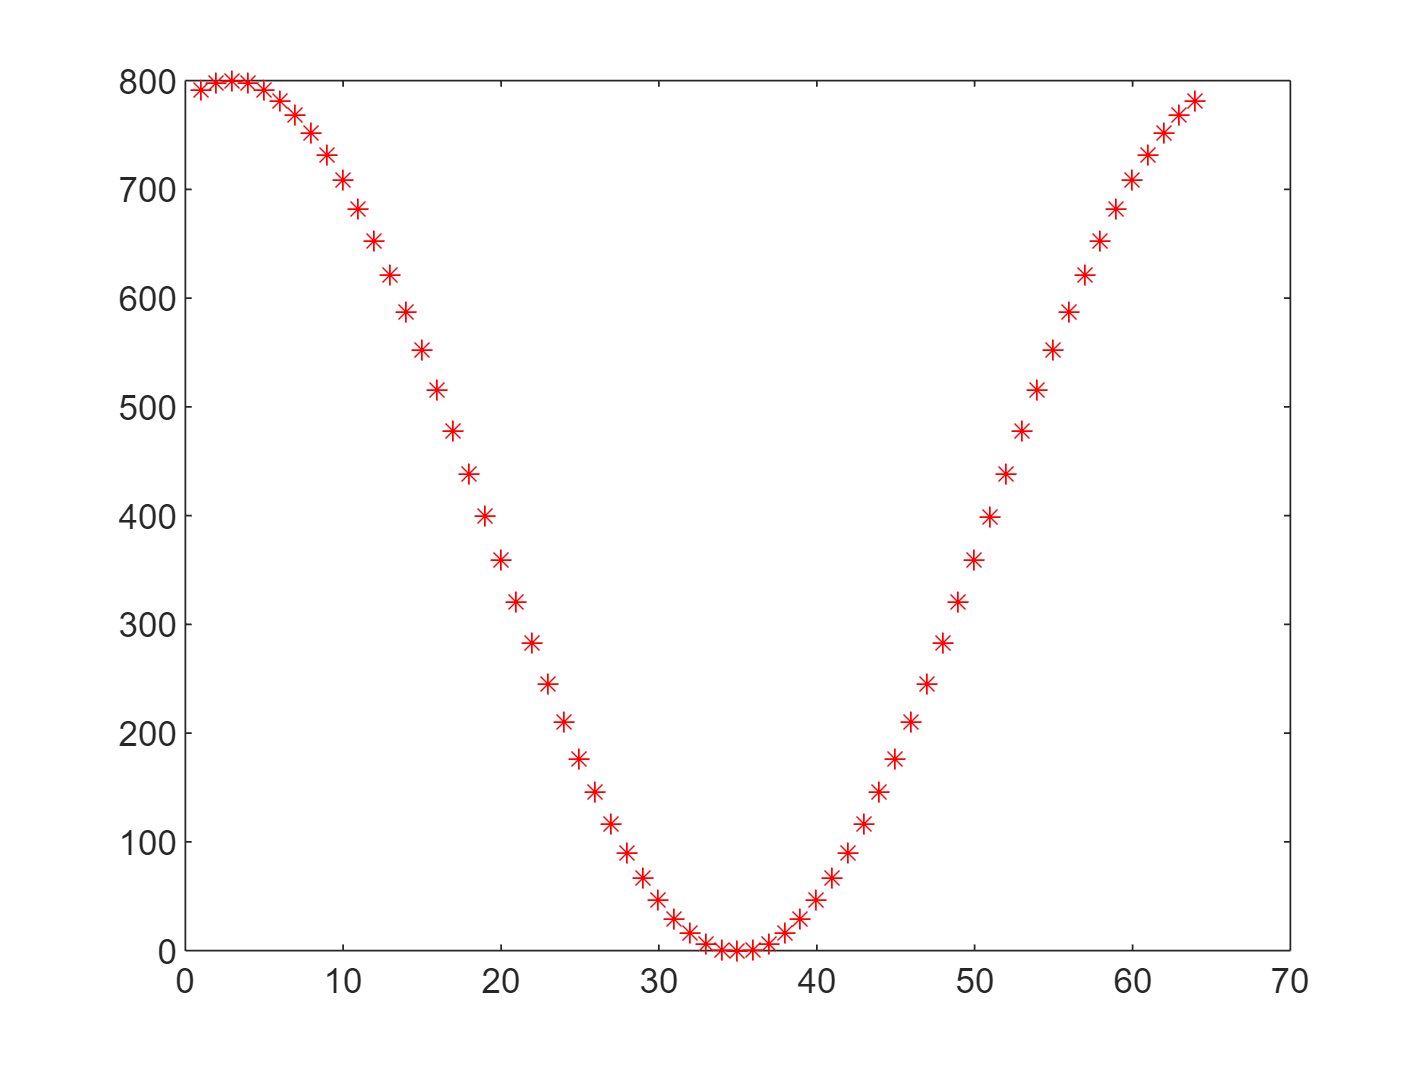

d = [792,798,800,798,792,782,769,752,732,709,682,653,622,588,553,516,478,439,400,360,321,283,246,211,177,146,117,90,67,47,30,17,7,1,0,1,7,17,30,47,67,90,117,146,177,211,246,283,321,360,399,439,478,516,553,588,622,653,682,709,732,752,769,782];
plot(x, d, 'r*')

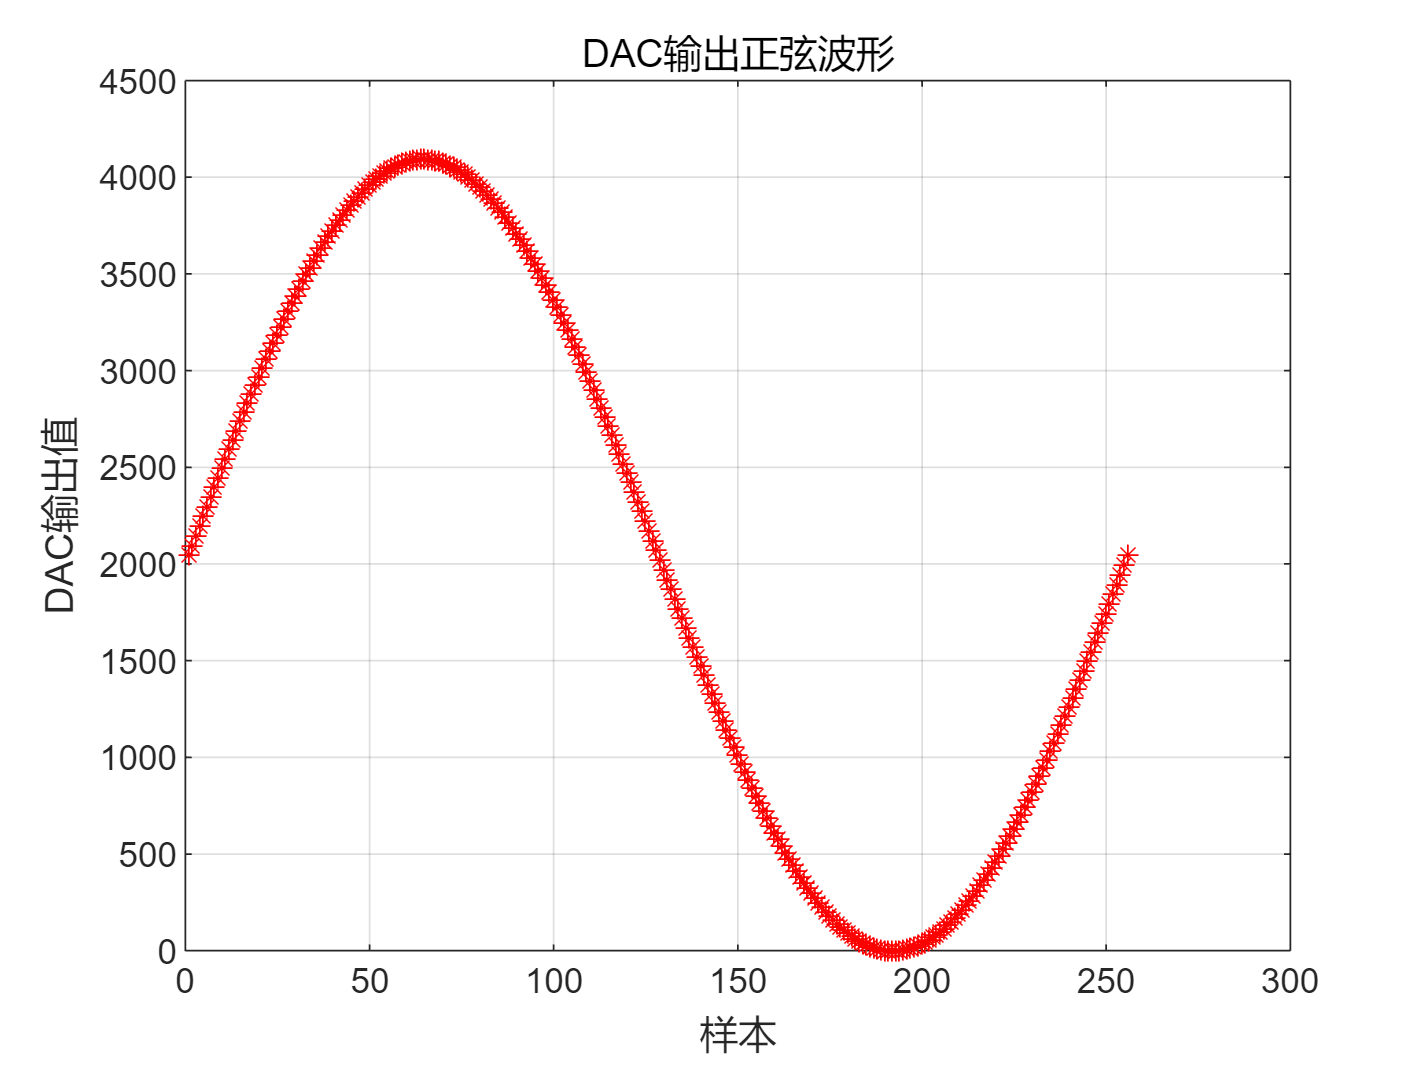

% DAC输出范围（12位DAC）
DAC_range = 2^12; % 4096个离散级别
 
% 生成正弦波形数组
num_samples = 256;
t = linspace(0, 2*pi, num_samples); % 时间从0到2*pi，等分成512份
sin_wave = sin(t);
 
% 将正弦波形归一化到DAC输出范围（0到4095）
normalized_sin_wave = (sin_wave + 1) * (DAC_range - 1) / 2;
 
% 将归一化的数组四舍五入为整数
dac_output_values = round(normalized_sin_wave);
 
% 绘制DAC输出波形
figure;
plot([1:1:256], dac_output_values, '*r')
title('DAC输出正弦波形');
xlabel('样本');
ylabel('DAC输出值');
grid on;

% 将数组保存到文件中
writematrix(dac_output_values, 'dac_output_values.txt');
disp('DAC输出值已保存到文件：dac_output_values.txt');

DAC输出值已保存到文件：dac_output_values.txt
